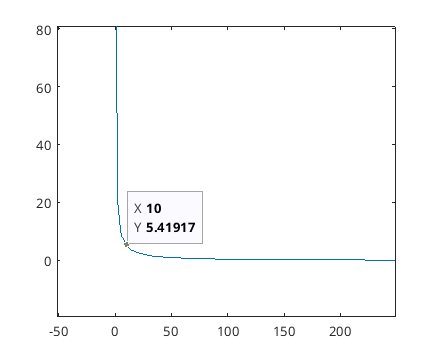


clear all;clc;
%fullname = get_full_filename('/home/naylak/Pictures/123.png');
a = imread('/home/kalyan/Pictures/123.png');
%svd of this a
a = imresize(a,[256 256]);
a = im2double(rgb2gray(a));
[U,S,V] = svd(a);
[m n] = size(a);

plot(diag(S))

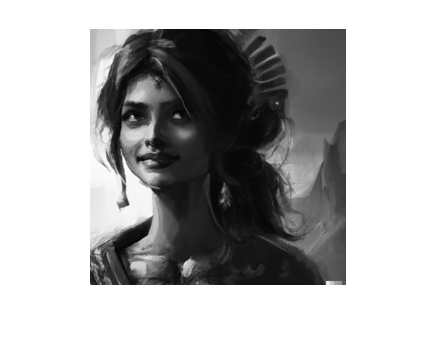


imshow(a)

Compression

clear all;clc;
a = imread('/home/kalyan/Pictures/123.jpg');

Error using imread>get_full_filename (line 570)
File "/home/kalyan/Pictures/123.jpg" does not exist.

Error in imread (line 377)
    fullname = get_full_filename(filename);

%svd of this a
a = imresize(a,[256 256]);
a = im2double(rgb2gray(a));
[U,S,V] = svd(a);
[m n] = size(a);

rec_img = zeros(m,n);
imshow(a)

for k = 1:50
    %show compression for each iteration
    im = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
    rec_img = rec_img + im;
    imshow(rec_img)
    pause(0.1)
end

Sakthi Idea


clear all;clc;
a = imread('/home/kalyan/Pictures/123.png');
%svd of this a
a = imresize(a,[256 256]);
a = im2double(rgb2gray(a));
[U,S,V] = svd(a);
[m n] = size(a);

rec_img = zeros(m,n);

for k = 1:40
    im = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
    rec_img = rec_img + im; 
end
imshow(a)
title("CoverImage")
b = imread('/home/naylak/Pictures/mandelbrot set kekw.png');
%this is going to be watermark for a , the cover image

b = imresize(b,[256 256]);
b = im2double(rgb2gray(b));
imshow(b)
title("Secret")
a = 0.01;
%SN = S + a*b;
Sn = S + a*b;

%obtaining watermarked image
watermarked_img = U*Sn*V';
figure,imshow(watermarked_img);
title("Secret Hidden")

%file size difference between original and compressed
imwrite(a,'original.jpg')
imwrite(watermarked_img,'compressed.jpg')
imwrite(S,"something.txt")